%% He Jiang

% mean
clear all
close all
clc

Data_path = "D:\MRES\Label\Catch011\";

Scan1_path = '20200528.nii';
Scan2_path = '20200610.nii';
Scan3_path = '20200617.nii';
Scan4_path = '20200626.nii';
% Scan5_path = '20200501.nii';


% read scans

Scan1 = niftiread(Data_path + Scan1_path);
Scan2 = niftiread(Data_path + Scan2_path);
Scan3 = niftiread(Data_path + Scan3_path);
Scan3(:,:,54) = -1000;
Scan4 = niftiread(Data_path + Scan4_path);
% Scan5 = niftiread(Data_path + Scan5_path);

Scan1_label =  niftiread(Data_path + 'R'+ Scan1_path);
Scan2_label =  niftiread(Data_path + 'R'+ Scan2_path);
Scan3_label =  niftiread(Data_path + 'R'+ Scan3_path);
Scan3_label(:,:,54) = 0;
Scan4_label =  niftiread(Data_path + 'R'+ Scan4_path);
% Scan5_label =  niftiread(Data_path + 'R'+ Scan5_path);
% 
Scan1(Scan1_label==0) = -1000;
Scan2(Scan2_label==0) = -1000;
Scan3(Scan3_label==0) = -1000;

Scan4(Scan4_label==0) = -1000;


Scan1 = Scan1(132:311,107:349,27);
Scan2 = Scan2(132:311,107:349,27);
Scan3 = Scan3(132:311,107:349,27);
Scan4 = Scan4(132:311,107:349,27);

Scan1_1 = reshape(Scan1,[],1);
Scan1_2 = reshape(Scan2,[],1);
Scan1_3 = reshape(Scan3,[],1);
Scan1_4 = reshape(Scan4,[],1);
T = single(cat(2,Scan1_1,Scan1_2,Scan1_3,Scan1_4));


[U, D, V] = svd(T);

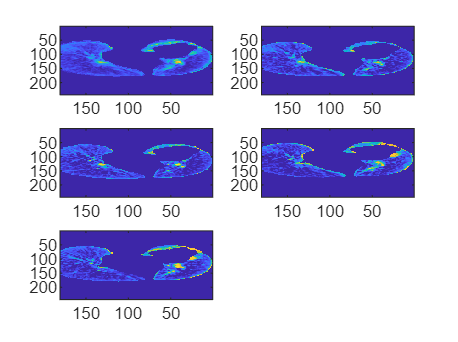

A = reshape(U(:,1),[180,243]);

subplot(3,2,1)
imagesc(A)
view([90 90])
subplot(3,2,2)
imagesc(Scan1)
view([90 90])
subplot(3,2,3)
imagesc(Scan2)
view([90 90])
subplot(3,2,4)
imagesc(Scan3)
view([90 90])
subplot(3,2,5)
imagesc(Scan4)
view([90 90])